format short g

group1 = string(y(1:300));
group1(group1 == "1") = "zd958";
group1(group1 == "2") = "jd20";

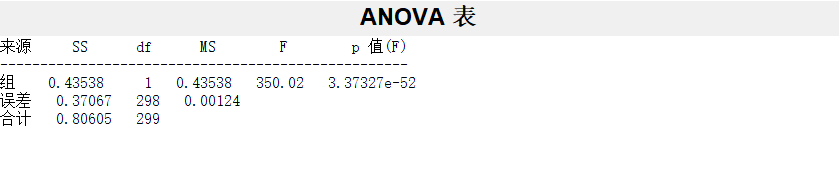

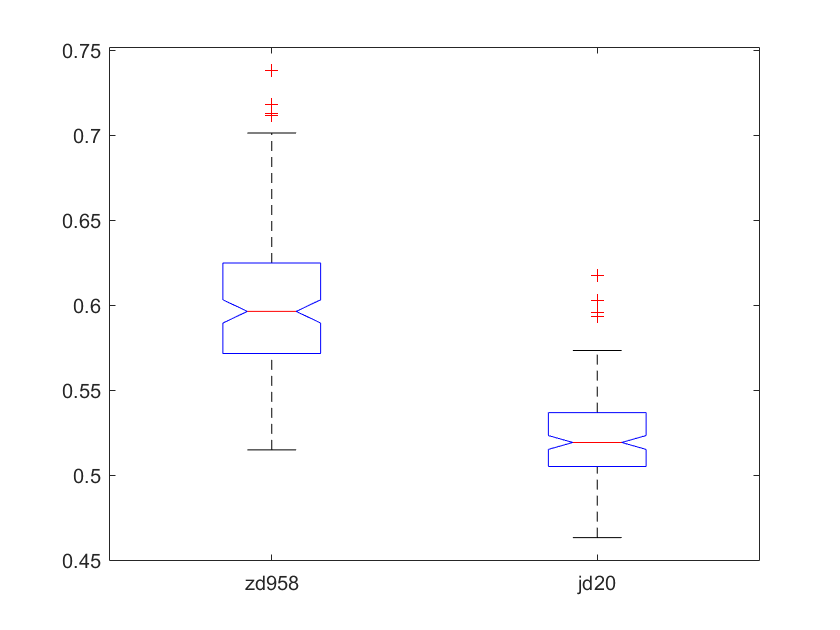

pvalue =    3.3733e-52


pvalue = anova1(X(1:300, 20), group1)

pvalues = zeros(1, size(X, 2));

for column = 1:size(X, 2)
    data = X(1:300, column);
    pvalue = anova1(data, group1, "off");
    pvalues(column) = pvalue;
end

sum(pvalues < power(0.1, 64))

ans =     16


[pvalues_sorted, pvalues_ind] = sort(pvalues);
shift_minp = effshift([pvalues_ind(1:20)])

shift_minp =         936.7       1149.8       940.43       1146.2       932.96       1153.4       1331.6       1142.6       1335.1         1157       944.16       929.23       925.49       1138.9       857.84       1328.1       850.28       854.06       1356.2       1135.3
